# **Homework**

**Quentin Gourier - SET1 - Ae421**

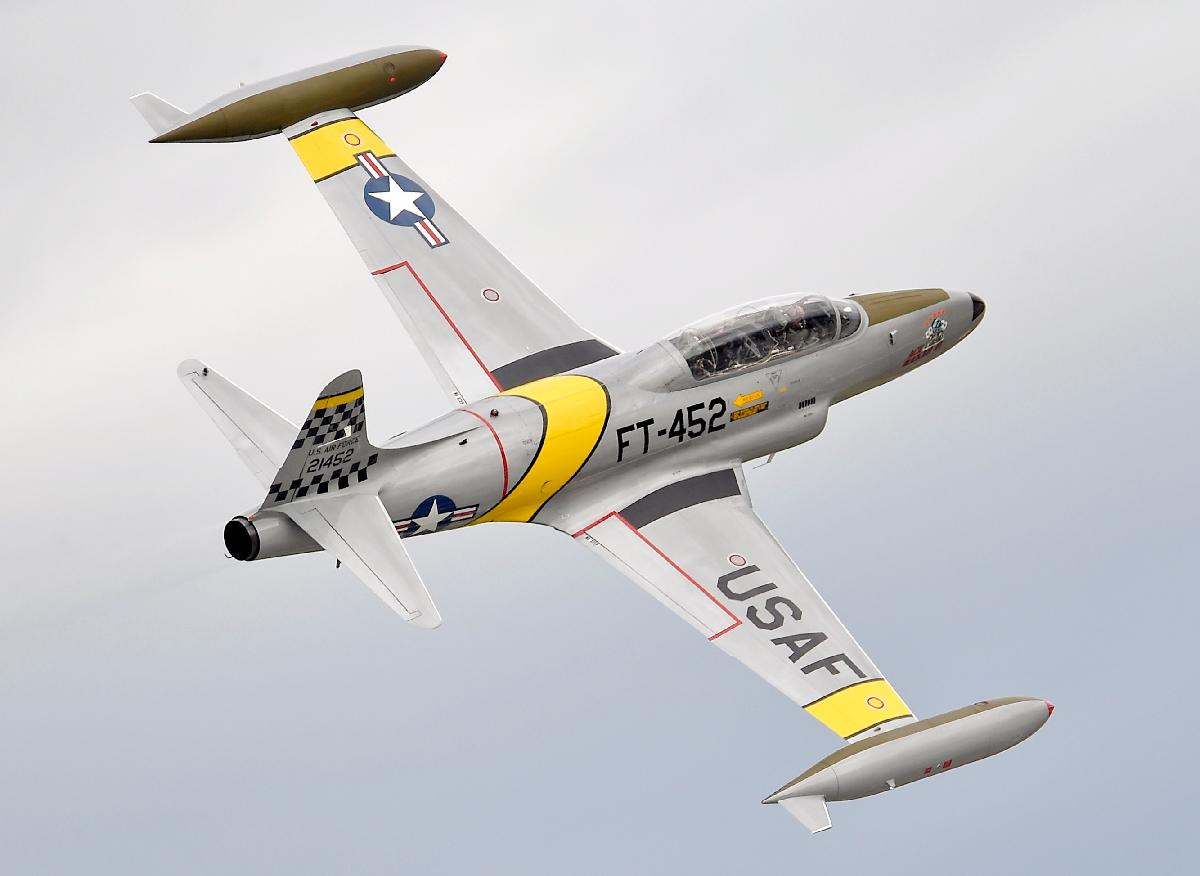

                                                                                                                         *T-33 jet trainer (model used in this assignment)*

*The whole code is available at this adress on my *[*GitHub*](https://github.com/quentingourier/dm_ae421/blob/main/dm.m)* repository or can be seen within Matlab selecting the "Output inline" option in the upper right corner.*

------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------------

### Introduction

*"The NT-33A variable stability airplane (Serial No. 51-4120) is an extensively modified T-33 jet trainer. The elevator, aileron and rudder controls in the front cockpit are disconnected from their respective control surfaces and have been connected to separate servomechanisms that make up an 'artificial feel' system.*

*In addition, the elevator, aileron and rudder control surfaces have been connected to individual servos which can be driven by a number of different inputs. These servos receive their electrical inputs from the artificial feel system (pilot's commands, position or force), attitude and rate gyros, accelerometers, dynamic pressure, _ vane and _ probe.*

*This arrangement, through a response-feedback system, allows the normal T-33 derivatives to be augmented to the extent that the handling qualities of many existing airplanes, future airplanes or hypothetical research configurations, can be simulated.*

*The original T-33 nose section has been replaced with the larger nose of an F-94 to provide the volume required for the electronic components of the response-feedback system and the recording equipment."**

*Aerodynamic data, for the most part, was taken from AFFDL-TR-70-71.*

*However, longitudinal data for the high lift configuration was obtained from LAL 1 27 and Mach number derivatives from NACA-RM-7116".*

Before calculating everything, we must have the variables declared. 

g = 9.81; %gravity

%aircraft data of lateral stability
h = 6096; %alt
rho = 0.653; %air density
U0 = 94.8; %speed
M = 0.3; %mach number
center_gravity = 0.263;
theta_0 = deg2rad(2.2); % 2.2 deg
omega_0 = 0;

%aircraft data
S = 21.81; %wing area
b = 11.44; %wingspan
c_bar = 2.05; %wing mean chord
A = 6.00; %aspect ratio
e = 0.89; %oswald number
m = 6214; %mass
I_xx = 30048.7; 
I_yy = 26639.8;
I_zz = 55299.8;
I_xz = 606;

C_L_0 = 0.813;
C_D_0 = 0.135;
C_Tx0 = 0.025;
C_m0 = 0;
C_mt0 = 0;

C_m_u = 0;
C_m_alpha = -0.401;
C_m_d_alpha = -5;
C_m_q = -10;
C_m_t_u = 0;
C_m_t_alpha = 0;
C_L_u = 0;
C_L_alpha = 5.22;
C_l_d_alpha = 1.74;
C_L_delta_t = 0;
C_L_q = 3.9;
C_D_u = 0;
C_D_alpha = 0.54;
C_D_d_alpha = 0;
C_D_delta_t = 0;
C_D_q = 0;
C_T_u = 0;
C_L_delta_e = 0.34;
C_D_delta_e = 0;
C_m_delta_e = -0.89;
C_m_delta_t = 0;

C_y_beta = -0.72; C_y_p = 0; C_y_r = 0;
C_l_beta = -0.127; C_l_p = -0.57; C_l_r = 0.2;
C_n_beta = 0.049; C_n_p = -0.045; C_n_r = -0.16;
C_y_delta_r = 0.17; C_l_delta_r = -0.002; C_n_delta_r = -0.073;
C_y_delta_a = 0; C_l_delta_a = 0.14; C_n_delta_a = -0.009;

q_bar = 0.5*rho*U0^2; %dynamic pressure

Yv = (q_bar*S*C_y_beta)/(m*U0);
Yp = (q_bar*S*b*C_y_p)/(2*m*U0);
Yr = (q_bar*S*b*C_y_r)/(2*m*U0);

Lv = (q_bar*S*b*C_l_beta)/(I_xx*U0);
Lp = (q_bar*S*b^2*C_l_p)/(2*I_xx*U0);
Lr = (q_bar*S*b^2*C_l_r)/(2*I_xx*U0);

Nv = (q_bar*S*b*C_n_beta)/(I_zz*U0);
Np = (q_bar*S*b^2*C_n_p)/(2*I_zz*U0);
Nr = (q_bar*S*b^2*C_n_r)/(2*I_zz*U0);

Y_delta_r = (q_bar*S*C_y_delta_r)/(m*U0);
L_delta_r = (q_bar*S*b*C_l_delta_r)/(I_xx*U0);
N_delta_r = (q_bar*S*b*C_n_delta_r)/(I_zz*U0);

Y_delta_a = (q_bar*S*C_y_delta_a)/(m*U0);
L_delta_a = (q_bar*S*b*C_l_delta_a)/(I_xx*U0);
N_delta_a = (q_bar*S*b*C_n_delta_a)/(I_zz*U0);

% aircraft matrix elements of longitudinal stability
q_bar = 0.5*rho*U0^2;
X_u = -((0.5*rho*U0^2*S)/(m*U0))*(2*C_D_0+C_D_u);
X_w = ((q_bar*S)/(m*U0))*(C_L_0-(2/(pi*e*A))*(C_L_0*C_L_alpha));
Z_u = -((0.5*rho*U0^2*S)/(m*U0))*(2*C_L_0+C_L_u);
Z_w = -((0.5*rho*U0^2*S)/(m*U0))*(C_D_0+C_L_alpha);
Z_q = ((0.5*rho*U0^2*S*c_bar)/(2*m*U0))*C_L_q;
M_u = ((0.5*rho*U0^2*S*c_bar)/(I_yy*U0))*C_m_u;
M_w = ((0.5*rho*U0^2*S*c_bar)/(I_yy*U0))*C_m_alpha;
M_d_w = ((0.5*rho*U0^2*S*c_bar^2)/(2*I_yy*U0^2))*C_m_d_alpha;
M_q = ((0.5*rho*U0^2*S*c_bar^2)/(2*I_yy*U0))*C_m_q;

% elevator derivatives
X_delta_e = ((0.5*rho*U0^2*S)/(m*U0))*C_D_delta_e;
Z_delta_e = ((0.5*rho*U0^2*S)/(m*U0))*C_L_delta_e;
M_delta_e = ((0.5*rho*U0^2*S*c_bar)/(I_yy*U0))*C_m_delta_e;

% throttle derivatives
X_delta_t = ((0.5*rho*U0^2*S)/(m*U0))*C_D_delta_t;
Z_delta_t = ((0.5*rho*U0^2*S)/(m*U0))*C_L_delta_t;
M_delta_t = ((0.5*rho*U0^2*S*c_bar)/(I_yy*U0))*C_m_delta_t;

### I. Longitudinal Dynamic Stability of Airplane

1.    The equations of longitudinal motion are the followings :

$m\overset{\ldotp }{U} =X-\textrm{mgsin}\left(\theta \right)+m\left(\textrm{rV}-\textrm{qW}\right)\;$ for axial translation

$m\dot{\;W} =Z+\textrm{mgcos}\left(\theta \right)\cos \left(\phi \;\right)+m\left(\textrm{qU}-\textrm{pV}\right)$ for vertical translation

$I_{y\;} \dot{\;q} =M-\left(I_x -I_z \right)\textrm{pr}-I_{\textrm{xz}} \left(\textrm{p²}+\textrm{r²}\right)$ for pitch motion

2.    The matrix A of the aircraft can be written as well as :

A = [X_u X_w 0 -g*cos(theta_0);
     Z_u Z_w U0 -g*sin(theta_0);
     M_u+Z_u*M_d_w M_w+Z_w*M_d_w M_q+U0*M_d_w 0;
     0 0 1 0]

A =    -0.0293    0.0334         0   -9.8028
   -0.1766   -0.5817   94.8000   -0.3766
    0.0005   -0.0192   -0.7987         0
         0         0    1.0000         0


B = [X_delta_e X_delta_t;
     Z_delta_e Z_delta_t;
     M_delta_e+Z_delta_e*M_d_w M_delta_t+Z_delta_t*M_d_w;
     0 0];

3.    The characteristic equation is found with :


$$\det \left(\lambda \;I-A\right)=0$$


char_equ = poly(A);
disp(char_equ(1,1)+"*r^4 + "+char_equ(1,2)+"*r^3 + "+char_equ(1,3)+"*r^2 + "+char_equ(1,4)+"*r + "+char_equ(1,5))

1*r^4 + 1.4098*r^3 + 2.3309*r^2 + 0.067781*r + 0.035865


4.     The eigenvalues of the system are :

lambda_vect = eig(A)

lambda_vect =   -0.6948 + 1.3433i
  -0.6948 - 1.3433i
  -0.0101 + 0.1248i
  -0.0101 - 0.1248i


Every eigenvalue has a negative real part, meaning the studied system is stable.

Using the well-known formulas we've seen during lectures, we have $\omega {\;}_{n_{\textrm{sp}\;} } ,\omega {\;}_{n_{p\;} } ,{\;\xi }_{\textrm{sp}} \;,{\;\xi }_p$ (natural frequency and damping factor for short-period and phugoid modes) :

lambda_1 = lambda_vect(1,1);
lambda_2 = lambda_vect(2,1);
lambda_3 = lambda_vect(3,1);
lambda_4 = lambda_vect(4,1);

omega = [sqrt(real(lambda_1)^2+imag(lambda_1)^2) sqrt(real(lambda_3)^2+imag(lambda_3)^2)];
omega_n_sp = max(omega)

omega_n_sp = 1.5124

omega_n_p = min(omega)

omega_n_p = 0.1252

ksi = [-real(lambda_1)/omega(1) -real(lambda_3)/omega(2)];
ksi_sp = max(ksi)

ksi_sp = 0.4594

ksi_p = min(ksi)

ksi_p = 0.0803

5.    The different modes of longitudinal stability : 

    By using the equations we can plot short-period mode combining $\omega \left(t\right)$ and $q\left(t\right)$ as well as phugoid mode combining $u\left(t\right)$ and $\theta \left(t\right)$ :

    a.    short-period mode

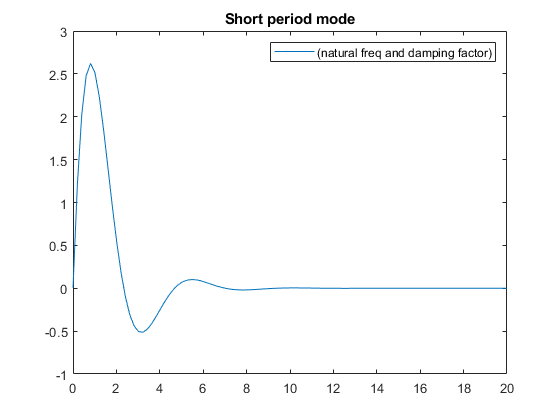

% 5. Different modes of longitudinal stability
% a. Short period mode
t2 = linspace(0,20);
w = exp(-omega_n_sp*ksi_sp*t2).*(omega_0/10*cos(omega_n_sp*sqrt(1-ksi_sp^2)*t2)+10*ksi_sp*omega_n_sp/(omega_n_sp*sqrt(1-ksi_sp^2))*sin(omega_n_sp*sqrt(1-ksi_sp^2)*t2));
q = exp(-omega_n_sp*ksi_sp*t2).*(theta_0/10*cos(omega_n_sp*sqrt(1-ksi_sp^2)*t2)+theta_0*ksi_sp*omega_n_sp/(omega_n_sp*sqrt(1-ksi_sp^2))*sin(omega_n_sp*sqrt(1-ksi_sp^2)*t2));
sp_mode = w + q;

figure
plot(t2, sp_mode);
legend({'(natural freq and damping factor)'})
title('Short period mode');

    b.    phugoid mode

% b. Phugoid mode
t = linspace(0,100);
u = exp(-omega_n_p*ksi_p*t).*(U0/10*cos(omega_n_p*sqrt(1-ksi_p^2)*t)+10*omega_n_p*ksi_p/(omega_n_p*sqrt(1-ksi_p^2))*sin(omega_n_p*sqrt(1-ksi_p^2)*t));
theta = exp(-omega_n_p*ksi_p*t).*(theta_0/10*cos(omega_n_p*sqrt(1-ksi_p^2)*t)+theta_0*ksi_p*omega_n_p/(omega_n_p*sqrt(1-ksi_p^2))*sin(omega_n_p*sqrt(1-ksi_p^2)*t));
phugoid_mode = u + theta;

figure
plot(t, phugoid_mode);
legend({'(natural freq and damping factor)'})
title('Phugoid mode');

6.    Curves of longitudinal motion :

    a.    $u\left(t\right)$

    b.    $\omega \left(t\right)$

    c.    $q\left(t\right)$

    d.    $\theta \left(t\right)$

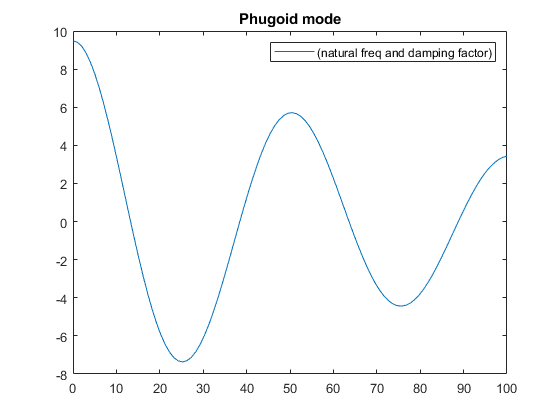

tile = tiledlayout(2,2);

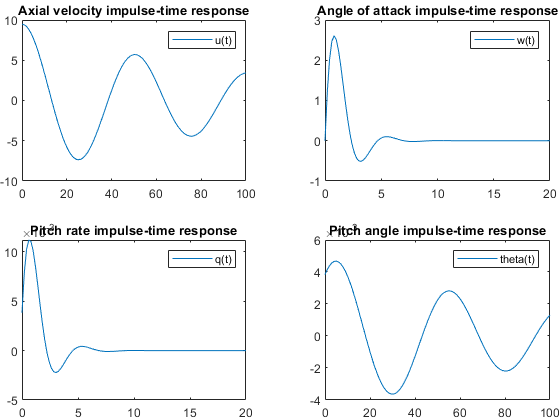

tile.TileSpacing = 'loose';
tile.Padding = 'tight';

% 6. Curves of longitudinal motion
% a. Axial velocity i function of time
nexttile
plot(t, u);
legend({'u(t)'})
title('Axial velocity impulse-time response');

% b. Angle of attack
nexttile
plot(t2, w);
legend({'w(t)'})
title('Angle of attack impulse-time response');

% c. Pitch rate
nexttile
plot(t2, q);
legend({'q(t)'})
title('Pitch rate impulse-time response');

% d. Pitch angle
nexttile
plot(t, theta);
legend({'theta(t)'})
title('Pitch angle impulse-time response');

7.    Transfer functions of each variable :

We can plot the Transfer functions thanks to the tf function of matlab and zpk which gives the equations in an appropriate way, better than manually inversing the matrix :

% 7. TFs of each variable

s = tf('s');
I = eye(size(A));
TF = zpk((s*I-A)\B);

Aircraft control response to Rudder :


$$\frac{v\left(s\right)}{\;\delta_r \left(s\right)}=\;$$


TF(1,2)

ans =
 
  0
 
Static gain.




$$\frac{p\left(s\right)}{\;\delta_r \left(s\right)}=$$


TF(2,2)

ans =
 
  0
 
Static gain.




$$\frac{r\left(s\right)}{\;\delta_r \left(s\right)}=$$


TF(3,2)

ans =
 
  0
 
Static gain.




$$\frac{\phi \left(s\right)}{\;\delta_r \left(s\right)}=$$


TF(4,2)

ans =
 
  0
 
Static gain.



Aircraft control response to Aileron :


$$\frac{v\left(s\right)}{\;\delta_a \left(s\right)}=\;$$


TF(1,1)

ans =
 
           0.0012321 (s+249.6) (s+0.8836)
  ------------------------------------------------
  (s^2 + 0.02011s + 0.01568) (s^2 + 1.39s + 2.287)
 
Continuous-time zero/pole/gain model.




$$\frac{p\left(s\right)}{\;\delta_a \left(s\right)}=\;$$


TF(2,1)

ans =
 
   0.036936 (s-118.1) (s^2 + 0.02549s + 0.01823)
  ------------------------------------------------
  (s^2 + 0.02011s + 0.01568) (s^2 + 1.39s + 2.287)
 
Continuous-time zero/pole/gain model.




$$\frac{r\left(s\right)}{\;\delta_a \left(s\right)}=\;$$


TF(3,1)

ans =
 
         -0.046338 s (s+0.5865) (s+0.03988)
  ------------------------------------------------
  (s^2 + 0.02011s + 0.01568) (s^2 + 1.39s + 2.287)
 
Continuous-time zero/pole/gain model.




$$\frac{\phi \left(s\right)}{\;\delta_a \left(s\right)}=\;$$


TF(4,1)

ans =
 
          -0.046338 (s+0.5865) (s+0.03988)
  ------------------------------------------------
  (s^2 + 0.02011s + 0.01568) (s^2 + 1.39s + 2.287)
 
Continuous-time zero/pole/gain model.



### II. Lateral Dynamic Stability of Airplane

1.    The equations of longitudinal motion are the followings :

$m\dot{\;V} =Y+\textrm{mgcos}\left(\theta \right)\sin \left(\phi \right)+m\left(\textrm{pW}-\textrm{rU}\right)$ for lateral translation

$I_{\textrm{xx}} \dot{\;p} =L+\left(I_{\textrm{yy}} -I_{\textrm{zz}} \right)\textrm{qr}+I_{\textrm{xz}} \left(\textrm{pq}+\dot{\;r} \right)$ for roll rotation

$I_{\textrm{zz}} \dot{\;r} =N+\left(I_{\textrm{xx}} -I_{\textrm{yy}} \right)\textrm{pq}-I_{\textrm{xz}} \left(\textrm{qr}-\dot{\;p} \right)$ for yaw rotation

2.    The matrix A of the aircraft can be written as well as :

A = [Yv Yp -(U0-Yr) g*cos(theta_0);
     Lv Lp Lr 0;
     Nv Np Nr 0;
     0 1 0 0]

A =    -0.0782         0  -94.8000    9.8028
   -0.0326   -0.8380    0.2940         0
    0.0068   -0.0359   -0.1278         0
         0    1.0000         0         0



B = [Y_delta_r Y_delta_a;
     L_delta_r L_delta_a;
     N_delta_r N_delta_a
     0 0];

3.    The characteristic equation is found again with :


$$\det \left(\lambda \;I-A\right)=0$$


char_equ = poly(A);
disp(char_equ(1,1)+"*r^4 + "+char_equ(1,2)+"*r^3 + "+char_equ(1,3)+"*r^2 + "+char_equ(1,4)+"*r + "+char_equ(1,5))

1*r^4 + 1.044*r^3 + 0.84192*r^2 + 0.98399*r + 0.021172


4.     The eigenvalues of the system are :

% 4. The eigenvalues of the system ?
eig(A)

ans =   -1.0863 + 0.0000i
   0.0321 + 0.9425i
   0.0321 - 0.9425i
  -0.0219 + 0.0000i


Laterally speaking, the system is not stable as seen previously. In fact, not every eigenvalue is a negative-real-part eigenvalue. (See the dutch roll value, we'll talk about it after).

We can now calculate $\omega {\;}_{n_{\textrm{dutch}\;\textrm{roll}} }$ and $\xi_{\textrm{dutch}\;\textrm{roll}}$  as :

[vect_propre, val_propre] = eig(A); %vecteur propre
lambda_dutch_roll_1 = val_propre(3,3);
lambda_dutch_roll_2 = val_propre(2,2); 
lambda_roll = val_propre(1,1);
lambda_spiral = val_propre(4,4);

% omega_n_dutch_roll = sqrt(real(lambda_dutch_roll_1)^2+imag(lambda_dutch_roll_1)^2)
omega_n_dutch_roll = sqrt(lambda_dutch_roll_1*lambda_dutch_roll_2)

omega_n_dutch_roll = 0.9430

% ksi_dutch_roll = -real(lambda_dutch_roll_1)/omega_n_dutch_roll
ksi_dutch_roll = (lambda_dutch_roll_1+lambda_dutch_roll_2)/(2*omega_n_dutch_roll)

ksi_dutch_roll = 0.0341

% % omega_n_dutch_roll = sqrt(Yv*Nr+Nv*(U0-Yr));
% % ksi_dutch_roll = -(Yv+Nr)/(2*omega_n_dutch_roll);

5.    The different modes of longitudinal stability : 

    a.    spiral mode

    b.    rolling mode

    c.    dutch-roll mode

By using the equations of the different modes seen in the lectures we're finally able to plot the graphs :

figure('Position', [1, 1, 1000, 400])
tile = tiledlayout(1,3);
tile.TileSpacing = 'loose';
tile.Padding = 'tight';
% 5. Different modes of lateral stability
% a. spiral mode
t2 = linspace(0,1000);
nexttile
xlim([0 600]);
sm1 = vect_propre(1,4)*exp(lambda_spiral*t2);
sm2 = vect_propre(2,4)*exp(lambda_spiral*t2);
sm3 = vect_propre(3,4)*exp(lambda_spiral*t2);
sm4 = vect_propre(4,4)*exp(lambda_spiral*t2);
hold on;
plot(t2, sm1)
plot(t2, sm2)
plot(t2, sm3)
plot(t2, sm4)
legend({'roll angle', 'yaw rate', 'side slip', 'roll rate'});
title('Spiral mode');
hold off;

nexttile
% b. rolling mode
t1 = linspace(0,10);
% xlim([0 10]);
ylim([-1 0.5]);
rm1 = vect_propre(1,1)*exp(lambda_roll*t1);
rm2 = vect_propre(2,1)*exp(lambda_roll*t1);
rm3 = vect_propre(3,1)*exp(lambda_roll*t1);
rm4 = vect_propre(4,1)*exp(lambda_roll*t1);
hold on;
plot(t1,rm1)
plot(t1,rm2)
plot(t1,rm3)
plot(t1,rm4)
legend({'side velocity', 'roll rate', 'yaw rate', 'side angle'})
title('Rolling mode');
hold off;

nexttile
% c. dutch roll mode
t3 = linspace(0,50);
% xlim([0 50]);
% ylim([-1 1]);
dr1 = vect_propre(1,2)*(exp(real(lambda_dutch_roll_2).*t3).*(cos(omega_n_dutch_roll.*t3)+ksi_dutch_roll*sin(omega_n_dutch_roll.*t3)));
dr2 = vect_propre(2,2)*(exp(real(lambda_dutch_roll_2).*t3).*(cos(omega_n_dutch_roll.*t3)+ksi_dutch_roll*sin(omega_n_dutch_roll.*t3)));
dr3 = vect_propre(3,2)*(exp(real(lambda_dutch_roll_2).*t3).*(cos(omega_n_dutch_roll.*t3)+ksi_dutch_roll*sin(omega_n_dutch_roll.*t3)));
dr4 = vect_propre(4,2)*(exp(real(lambda_dutch_roll_2).*t3).*(cos(omega_n_dutch_roll.*t3)+ksi_dutch_roll*sin(omega_n_dutch_roll.*t3)));
hold on;
plot(t3, dr1)
plot(t3, dr2)

plot(t3, dr3)

plot(t3, dr4)

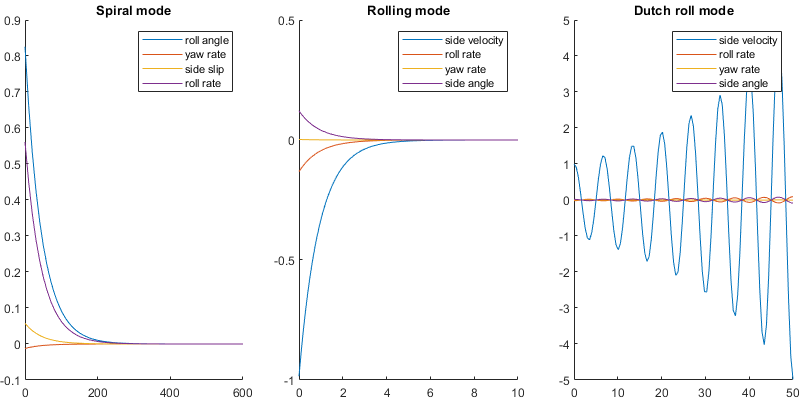

legend({'side velocity', 'roll rate', 'yaw rate', 'side angle'});
title('Dutch roll mode'); 
hold off;

6.    Curves of lateral motion :

    a.    $u\left(t\right)$

    b.    $\omega \left(t\right)$

    c.    $q\left(t\right)$

    d.    $\theta \left(t\right)$

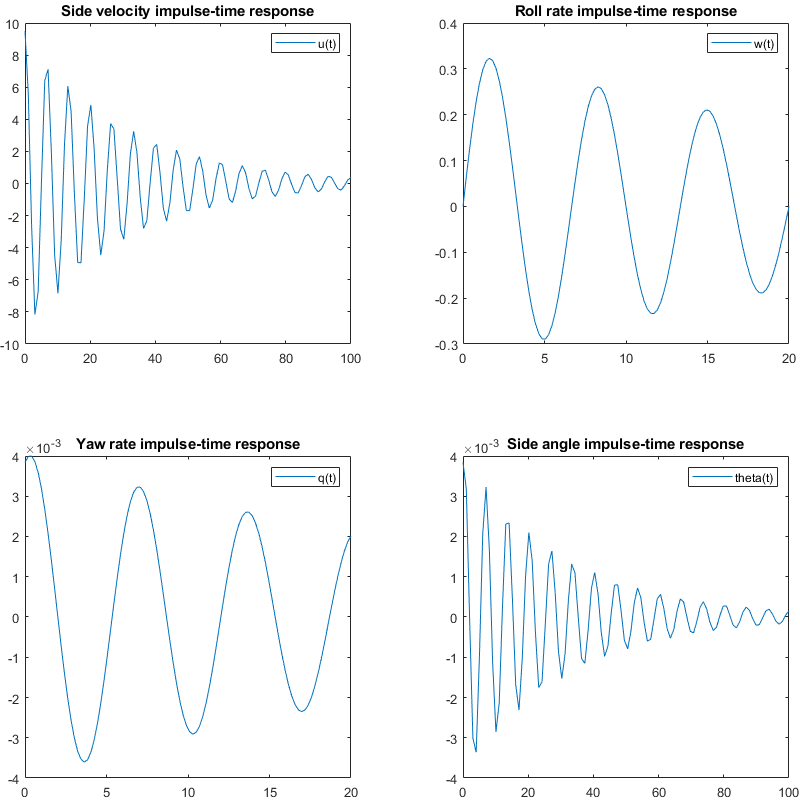

figure('Position', [1, 1, 1000, 800])
tile = tiledlayout(2,2);
tile.TileSpacing = 'loose';
tile.Padding = 'tight';
t = linspace(0, 100);
t2 = linspace(0, 20);

u = exp(-omega_n_dutch_roll*ksi_dutch_roll*t).*(U0/10*cos(omega_n_dutch_roll*sqrt(1-ksi_dutch_roll^2)*t)+10*omega_n_dutch_roll*ksi_dutch_roll/(omega_n_dutch_roll*sqrt(1-ksi_dutch_roll^2))*sin(omega_n_dutch_roll*sqrt(1-ksi_dutch_roll^2)*t));
theta = exp(-omega_n_dutch_roll*ksi_dutch_roll*t).*(theta_0/10*cos(omega_n_dutch_roll*sqrt(1-ksi_dutch_roll^2)*t)+theta_0*ksi_dutch_roll*omega_n_dutch_roll/(omega_n_dutch_roll*sqrt(1-ksi_dutch_roll^2))*sin(omega_n_dutch_roll*sqrt(1-ksi_dutch_roll^2)*t));
w = exp(-omega_n_dutch_roll*ksi_dutch_roll*t2).*(omega_0/10*cos(omega_n_dutch_roll*sqrt(1-ksi_dutch_roll^2)*t2)+10*ksi_dutch_roll*omega_n_dutch_roll/(omega_n_dutch_roll*sqrt(1-ksi_dutch_roll^2))*sin(omega_n_dutch_roll*sqrt(1-ksi_dutch_roll^2)*t2));
q = exp(-omega_n_dutch_roll*ksi_dutch_roll*t2).*(theta_0/10*cos(omega_n_dutch_roll*sqrt(1-ksi_dutch_roll^2)*t2)+theta_0*ksi_dutch_roll*omega_n_dutch_roll/(omega_n_dutch_roll*sqrt(1-ksi_dutch_roll^2))*sin(omega_n_dutch_roll*sqrt(1-ksi_dutch_roll^2)*t2));


% 6. Curves of longitudinal motion
% a. Axial velocity i function of time
nexttile
plot(t, u);
legend({'u(t)'})
title('Side velocity impulse-time response');

% b. Angle of attack
nexttile
plot(t2, w);
legend({'w(t)'})
title('Roll rate impulse-time response');

% c. Pitch rate
nexttile
plot(t2, q);
legend({'q(t)'})
title('Yaw rate impulse-time response');

% d. Pitch angle
nexttile
plot(t, theta);
legend({'theta(t)'})
title('Side angle impulse-time response');

7.    Transfer functions of each variable :

We can plot the Transfer functions thanks to the tf function of matlab and zpk which gives the equations in an appropriate way, better than manually inversing the matrix :

% 7. TFs of each variable
s = tf('s');
I = eye(size(A));
TF = zpk((s*I-A)\B);

Aircraft control response to Rudder :


$$\frac{v\left(s\right)}{\;\delta_r \left(s\right)}=\;$$


TF(1,2)

ans =
 
           0.11915 (s+4.754) (s+0.07319)
  -----------------------------------------------
  (s+1.086) (s+0.02192) (s^2 - 0.06423s + 0.8893)
 
Continuous-time zero/pole/gain model.




$$\frac{p\left(s\right)}{\;\delta_r \left(s\right)}=$$


TF(2,2)

ans =
 
        0.035981 s (s^2 + 0.1958s + 0.5498)
  -----------------------------------------------
  (s+1.086) (s+0.02192) (s^2 - 0.06423s + 0.8893)
 
Continuous-time zero/pole/gain model.




$$\frac{r\left(s\right)}{\;\delta_r \left(s\right)}=$$


TF(3,2)

ans =
 
    -0.0012569 (s-0.7447) (s^2 + 2.69s + 2.149)
  -----------------------------------------------
  (s+1.086) (s+0.02192) (s^2 - 0.06423s + 0.8893)
 
Continuous-time zero/pole/gain model.




$$\frac{\phi \left(s\right)}{\;\delta_r \left(s\right)}=$$


TF(4,2)

ans =
 
         0.035981 (s^2 + 0.1958s + 0.5498)
  -----------------------------------------------
  (s+1.086) (s+0.02192) (s^2 - 0.06423s + 0.8893)
 
Continuous-time zero/pole/gain model.



Aircraft control response to Aileron :


$$\frac{v\left(s\right)}{\;\delta_a \left(s\right)}=\;$$


TF(1,1)

ans =
 
     0.018468 (s+52.46) (s+0.8674) (s-0.03573)
  -----------------------------------------------
  (s+1.086) (s+0.02192) (s^2 - 0.06423s + 0.8893)
 
Continuous-time zero/pole/gain model.




$$\frac{p\left(s\right)}{\;\delta_a \left(s\right)}=\;$$


TF(2,1)

ans =
 
        -0.00051402 s (s^2 + 7.21s + 62.56)
  -----------------------------------------------
  (s+1.086) (s+0.02192) (s^2 - 0.06423s + 0.8893)
 
Continuous-time zero/pole/gain model.




$$\frac{r\left(s\right)}{\;\delta_a \left(s\right)}=\;$$


TF(3,1)

ans =
 
   -0.010195 (s+1.115) (s^2 - 0.2128s + 0.2901)
  -----------------------------------------------
  (s+1.086) (s+0.02192) (s^2 - 0.06423s + 0.8893)
 
Continuous-time zero/pole/gain model.




$$\frac{\phi \left(s\right)}{\;\delta_a \left(s\right)}=\;$$


TF(4,1)

ans =
 
         -0.00051402 (s^2 + 7.21s + 62.56)
  -----------------------------------------------
  (s+1.086) (s+0.02192) (s^2 - 0.06423s + 0.8893)
 
Continuous-time zero/pole/gain model.

